# Behavioral and Self-Report Publication Plots for Sun et al., 2026

Michael Sun, Ph.D.

## Housekeeping

Note that the analysis requires the use of CANLabCore Tools to be downloaded in a Matlab working directory.

% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

CANLab Core is installed.


## Load Data

Load the .mat file that contains:

- **demo_data: **Data table on demographics for each of the 9 subjects.

- **calibration_data: **Data from the calibration sessions.

- **scan_data:** Data from fMRI scan sessions.

load('BSR_Data.mat')

## Data Overview

### Calibration Data

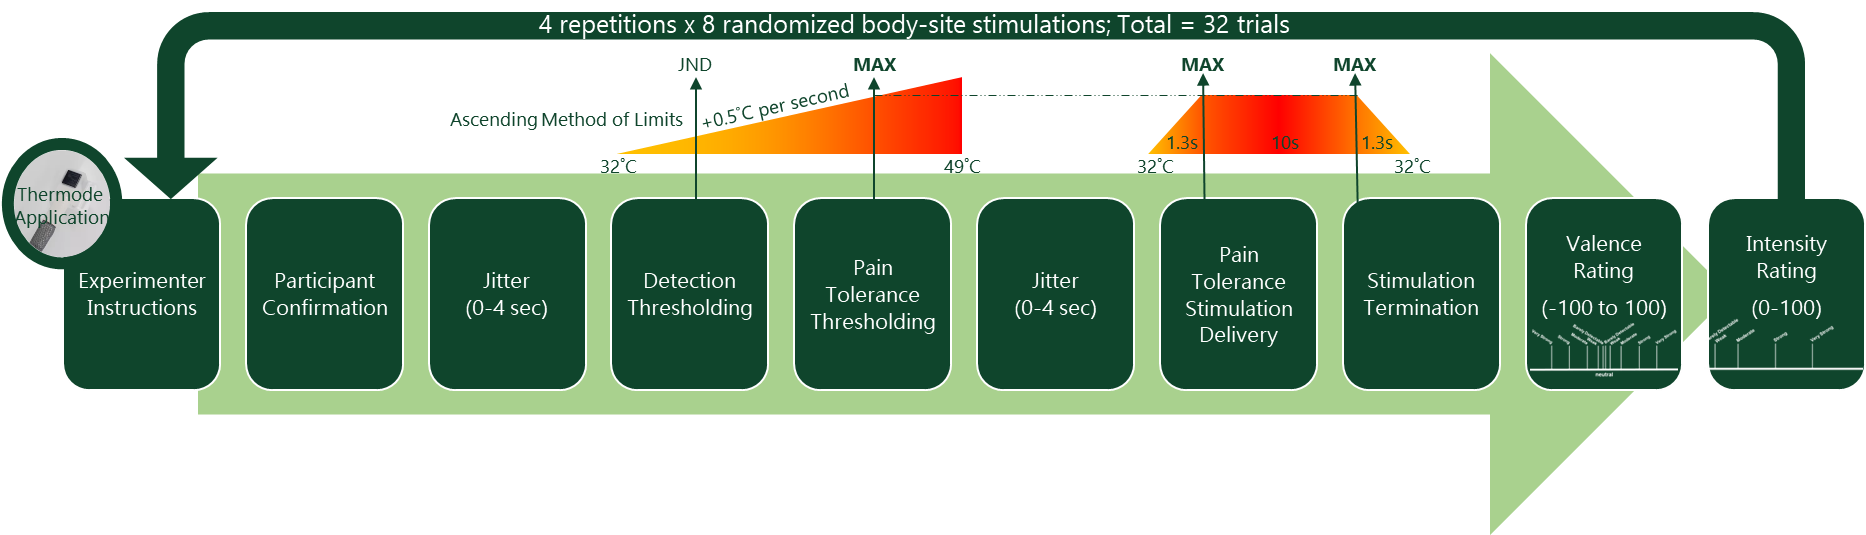

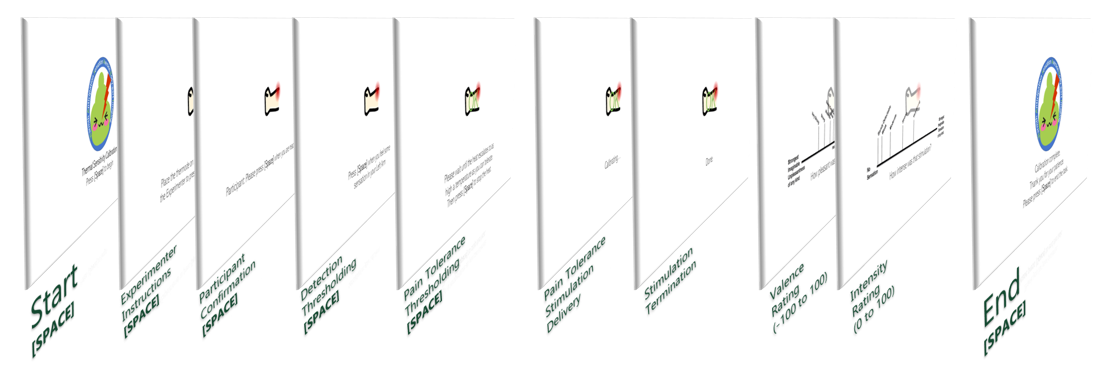

The table **calibration_data** contains trial-level data for the Ascending Method of Limits calibration task for each subject that occurred before the scan sessions. It contains the following information:

- **subjectid:** The internal study-level ID assigned to the subject.

- **body_site: **The body site that was stimulated on that trial.

- **trial: **The trial number, from 1-32, indicating the trial whereby the subject was delivered thermal stimulation to an indicated body site.

- **repetition:** Indicates the number of times that body site had been stimulated for that subject.

- **stim_temp: **The temperature at which the subject indicated that they could sense a stimulation (from 32 degrees room temperature), used to determine their ***detection threshold****.*

- **hot_temp:** The temperature at which the subject indicated that they could no longer tolerate the thermal stimulation (from 32 degrees room temperature), used to determine their ***pain tolerance threshold****.*

- **valence_rating: **Post pain tolerance stimulation trial bipolar valence rating from negative (bad) to positive (good). NaNs indicate that the subject mispressed and did not give a valid rating for that trial.

- **intensity_rating: **Post pain tolerance stimulation trial unipolar intensity rating.

disp(calibration_data)

    subjectid    trial    repetition    body_site     stim_temp    hot_temp    valence_rating    intensity_rating
    _________    _____    __________    __________    _________    ________    ______________    ________________

        5          1          1         Chest             39           48           -35                 33       
        5          2          1         Left Arm          35         46.5           -29                 25       
        5          3          1         Right Leg         42           46           -24                 28       
        5          4          1         Right Face      40.5           49           -35                 33       
        5          5          1         Rig

### Scan Data

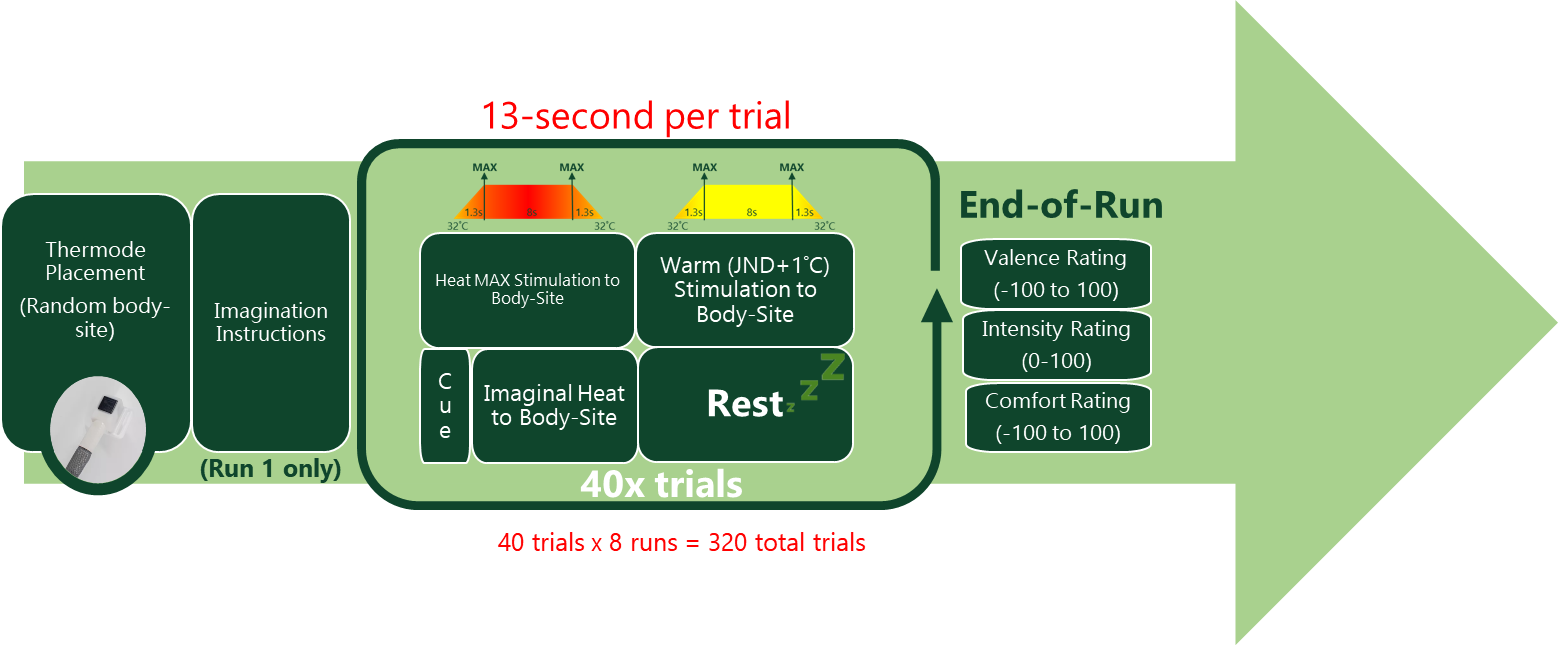

The table **scan_data** contains fMRI run-level data for end-of-run self-report questions. It contains the following information:

- **subjectid: **The internal study-level ID assigned to the subject.

- **body_site: **The body site that was stimulated on that trial.

- **session: **The session number for that subject.

- **run: **The run number nested within session.

- **body_site: **The body site that was stimulated on that trial.

- **hot temp: **The stimulation temperature delivered to the body site during the fMRI run during the Hot trials. This is the ***pain tolerance threshold*** set during calibration*.*

- **warm temp: **The stimulation temperature delivered to the body site during the fMRI run during the Warm trials. This is the ***detection threshold*** set during calibration +1 degree Celsius*.*

- **valence_rating: **Post-run bipolar valence rating from negative (bad) to positive (good). NaNs indicate that the subject did not give a valid rating for that run (mispress).

- **intensity_rating: **Post-run unipolar intensity rating. NaNs indicate that the subject did not give a valid rating for that run (mispress).

- **comfort_rating: **Post-run bipolar body comfort rating. NaNs indicate that the subject did not give a valid rating for that run (mispress).

disp(scan_data)

    subjectid    body_site     session    run    hot_temp    warm_temp    intensity_rating    valence_rating    comfort_rating
    _________    __________    _______    ___    ________    _________    ________________    ______________    ______________

        1        Abdomen          2        3         47          39            8.3333            -0.98765           68.889    
        1        Abdomen          4        4         47          39             36.42             -21.852            46.79    
        1        Abdomen          6        3         47          39            37.037             -24.074           42.346    
        1        Abdomen          8        2         47   

## Table 1: Participant Demographics

disp(demo_data(:,1:13));

    Subject    Sex    Age        Race        Handedness    Detection Threshold M    Detection Threshold SE    Pain Tolerance M    Pain Tolerance SE    Calibration Intensity M    Calibration Intensity SE    Calibration Valence M    Calibration Valence SE
    _______    ___    ___    ____________    __________    _____________________    ______________________    ________________    _________________    _______________________    ________________________    _____________________    ______________________
       1        M     50s    White               L

## Figure S1: Subject-Level Variability of Calibration Behavior

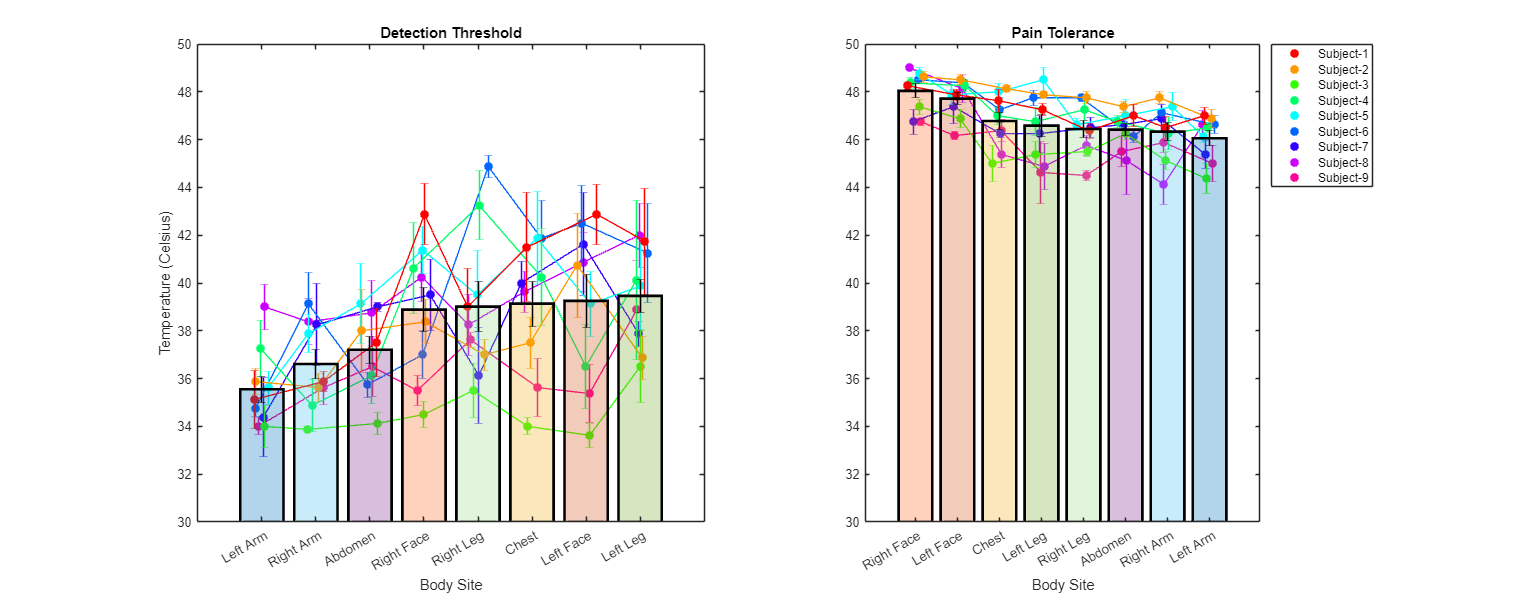

%% Prep data
detection_thr = calibration_data.stim_temp;
pain_tolerance      = calibration_data.hot_temp;
body_site     = calibration_data.body_site;
subjectid     = calibration_data.subjectid;

% Unique levels
unique_body_sites = cellstr(unique(body_site));
unique_subjects   = cellstr(unique(subjectid));

% Convert to cellstring
body_site     = cellstr(calibration_data.body_site);
subjectid     = cellstr(calibration_data.subjectid);

%% Compute stats: detection threshold
[det_grand_mean, det_grand_se, det_subj_mean, det_subj_se] = ...
    compute_subject_stats(detection_thr, body_site, subjectid, ...
                          unique_body_sites, unique_subjects);

detection_thr_mean = det_grand_mean;
detection_thr_se   = det_grand_se;

% Sort body sites for detection (ascending)
[det_grand_mean_sorted, sort_idx_det] = sort(det_grand_mean, 'ascend');
det_grand_se_sorted   = det_grand_se(sort_idx_det);
bs_sorted_det         = unique_body_sites(sort_idx_det);
det_subj_mean_sorted  = det_subj_mean(sort_idx_det, :);
det_subj_se_sorted    = det_subj_se(sort_idx_det, :);

% Body-site colors (assume cmap exists)
bs_colors_det = cmap(sort_idx_det, :);

%% Compute stats: pain tolerance
[pain_grand_mean, pain_grand_se, pain_subj_mean, pain_subj_se] = ...
    compute_subject_stats(pain_tolerance, body_site, subjectid, ...
                          unique_body_sites, unique_subjects);

pain_tol_mean = pain_grand_mean;
pain_tol_se   = pain_grand_se;

% Sort body sites for pain (descending)
[pain_grand_mean_sorted, sort_idx_pain] = sort(pain_grand_mean, 'descend');
pain_grand_se_sorted   = pain_grand_se(sort_idx_pain);
bs_sorted_pain         = unique_body_sites(sort_idx_pain);
pain_subj_mean_sorted  = pain_subj_mean(sort_idx_pain, :);
pain_subj_se_sorted    = pain_subj_se(sort_idx_pain, :);

bs_colors_pain = cmap(sort_idx_pain, :);

%% Subject color map (shared)
colors = hsv(length(unique_subjects) + 1);
colors = colors([1:2, 4:end], :);   % drop one color because of visibility issues

%% Plot
figure('Position', [0 0 2560 1000]);

% Left: detection threshold
subplot(1, 2, 1);
plot_body_site_bars(det_grand_mean_sorted, det_grand_se_sorted, ...
    det_subj_mean_sorted, det_subj_se_sorted, ...
    bs_sorted_det, bs_colors_det, unique_subjects, colors);
xlabel('Body Site');
ylabel('Temperature (Celsius)');
ylim([30 50]);
title('Detection Threshold');

% Right: pain threshold
subplot(1, 2, 2);
plot_body_site_bars(pain_grand_mean_sorted, pain_grand_se_sorted, ...
    pain_subj_mean_sorted, pain_subj_se_sorted, ...
    bs_sorted_pain, bs_colors_pain, unique_subjects, colors);
xlabel('Body Site');
yticks(30:2:50);
ylabel('');
ylim([30 50]);
title('Pain Tolerance');

% Add legend (do it once, on the right subplot)
legend_labels = strcat('Subject-', unique_subjects(:));

% Preallocate graphic handles
nSubs = numel(unique_subjects);
legend_handles = gobjects(nSubs, 1);

% Create invisible dummy points just for the legend
hold on;
for s = 1:nSubs
    legend_handles(s) = plot(NaN, NaN, 'o', ...
        'MarkerFaceColor', colors(s, :), ...
        'MarkerEdgeColor', colors(s, :), ...
        'MarkerSize', 6, ...
        'LineStyle', 'none');
end

% Now make the legend from those dummy handles
legend(legend_handles, legend_labels, 'Location', 'BestOutside');

% legend off;

## Figure 2A: Calibration Behavior

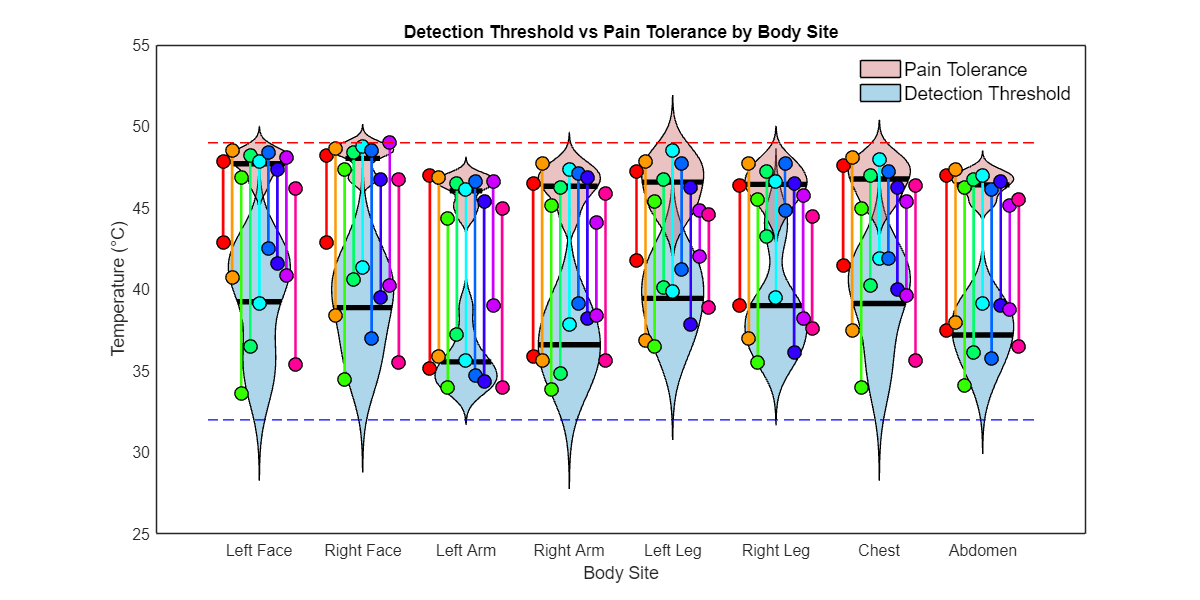

% 1) Prepare data matrices (subjects x bodysites)
detection_data = det_subj_mean';   % [numSubjects x numBodysites]
pain_data      = pain_subj_mean';  % [numSubjects x numBodysites]

[numSubjects, numBodysites] = size(detection_data);

% 2) Create figure and axes
figure('Color', 'w', 'Position', [100 100 1200 600]);
ax = axes;
hold(ax, 'on');
set(ax, 'Layer', 'top');

positions    = 1:numBodysites;  % x positions for bodysites
offset_range = 0.35;            % max horizontal spread for subject points
offsets      = linspace(-offset_range, offset_range, numSubjects);  % symmetric offsets

% 3) Violin plots with robust coloring
% Capture existing patches to detect new ones per call
p0 = findobj(ax, 'Type', 'Patch');
v_det = violinplot(detection_data, positions, 'nopoints', 'mc', 'k');   % detection
p1 = findobj(ax, 'Type', 'Patch');
det_patches = setdiff(p1, p0);   % newly created patches from first violinplot

v_pain = violinplot(pain_data, positions, 'nopoints', 'mc', 'k');       % pain
p2 = findobj(ax, 'Type', 'Patch');
pain_patches = setdiff(p2, p1);  % newly created patches from second violinplot

% Set colors and transparency
set(det_patches,  'FaceColor', [0.2 0.6 0.8], 'FaceAlpha', 0.4);  % detection (blue-ish)
set(pain_patches, 'FaceColor', [0.8 0.4 0.4], 'FaceAlpha', 0.4);  % pain (red-ish)

for b = 1:numBodysites
    x_center = positions(b);
    for s = 1:numSubjects
        x_det  = x_center + offsets(s);
        x_pain = x_det;  % same x for detection and pain for that subject/site

        y_det  = detection_data(s, b);
        y_pain = pain_data(s, b);

        % Connecting line
        line([x_det x_pain], [y_det y_pain], ...
            'Color', colors(s, :), ...
            'LineWidth', 2.0);

        % Detection point
        scatter(x_det, y_det, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.0);

        % Pain point
        scatter(x_pain, y_pain, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.0);
    end
end

% 4) Reference lines
hline(49, 'r--');
hline(32, 'b--');

% 5) Final formatting
xticks(positions);
xticklabels(bodysite_labels);   % assumes bodysite_labels matches sorted order
xlabel('Body Site');
ylabel('Temperature (°C)');
title('Detection Threshold vs Pain Tolerance by Body Site');

% 6) Legend for the two violin groups
% Use dummy patches so legend is stable and independent of violin internals
hPain = patch(NaN, NaN, [0.8 0.4 0.4], 'FaceAlpha', 0.4);
hDet  = patch(NaN, NaN, [0.2 0.6 0.8], 'FaceAlpha', 0.4);
legend([hPain, hDet], {'Pain Tolerance', 'Detection Threshold'}, ...
    'Location', 'northeast');
grid(ax, 'off');
set(ax, 'FontSize', 12, 'Box', 'on');
axis(ax, 'auto');
hold(ax, 'off');


% 7) Optional subject legend
% Create invisible dummy points just for the legend
% hold on;
% for s = 1:nSubs
%     legend_handles(s) = plot(NaN, NaN, 'o', ...
%         'MarkerFaceColor', colors(s, :), ...
%         'MarkerEdgeColor', colors(s, :), ...
%         'MarkerSize', 6, ...
%         'LineStyle', 'none');
% end
% 
% % Now make the legend from those dummy handles
% legend(legend_handles, legend_labels, 'Location', 'BestOutside');
% legend off;

## Figure S2A: Subject-Level Variability of Calibration Self-Report

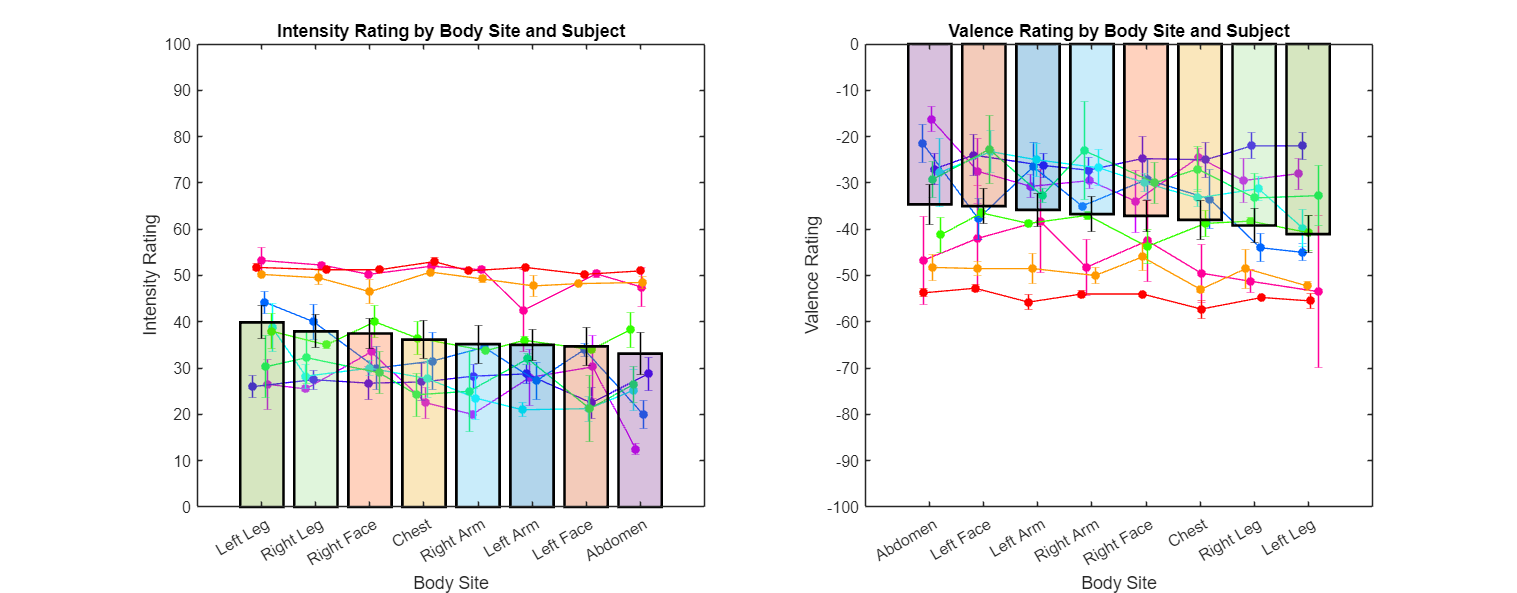

body_site = calibration_data.body_site;    % categorical or char
subjectid = calibration_data.subjectid;    % numeric

% Body-site order
correct_order = {
    'Left Face';
    'Right Face';
    'Left Arm';
    'Right Arm';
    'Left Leg';
    'Right Leg';
    'Chest';
    'Abdomen';
};

% Subject colors
colors = hsv(length(unique_subjects) + 1);
colors = colors([1:2,4:end], :);   % drop one color due to visibility

%% === Intensity plot (left subplot) ===

intensity_metric = calibration_data.intensity_rating;

[grand_mean_int, grand_se_int, subj_mean_int, subj_se_int, bs_ordered_int] = ...
    compute_stats_by_bodysite(intensity_metric, body_site, subjectid, ...
                              correct_order, unique_subjects);

% Keep subject-level matrices (unsorted)
intensity_means = subj_mean_int';   % subjects x bodysites
intensity_se    = subj_se_int';

% Sort by descending grand mean for plotting
[grand_mean_int_sorted, sort_idx_int] = sort(grand_mean_int, 'descend');
grand_se_int_sorted   = grand_se_int(sort_idx_int);
bs_sorted_int         = bs_ordered_int(sort_idx_int);
subj_mean_int_sorted  = subj_mean_int(sort_idx_int, :);
subj_se_int_sorted    = subj_se_int(sort_idx_int, :);

% Body-site colors (sorted)
bs_colors_int = cmap(sort_idx_int, :);

figure('Position', [0 0 2560 1000]);

subplot(1, 2, 1);
plot_body_site_bars_basic( ...
    grand_mean_int_sorted, grand_se_int_sorted, ...
    subj_mean_int_sorted, subj_se_int_sorted, ...
    bs_sorted_int, bs_colors_int, ...
    unique_subjects, colors);

xlabel('Body Site');
ylabel('Intensity Rating');
ylim([0 100]);
title('Intensity Rating by Body Site and Subject');

%% === Valence plot (right subplot) ===

valence_metric   = calibration_data.valence_rating;

[grand_mean_val, grand_se_val, subj_mean_val, subj_se_val, bs_ordered_val] = ...
    compute_stats_by_bodysite(valence_metric, body_site, subjectid, ...
                              correct_order, unique_subjects);

% Keep subject-level matrices (unsorted) for later use
valence_means = subj_mean_val';    % subjects x bodysites
valence_se    = subj_se_val';

% Sort by descending grand mean for plotting
[grand_mean_val_sorted, sort_idx_val] = sort(grand_mean_val, 'descend');
grand_se_val_sorted   = grand_se_val(sort_idx_val);
bs_sorted_val         = bs_ordered_val(sort_idx_val);
subj_mean_val_sorted  = subj_mean_val(sort_idx_val, :);
subj_se_val_sorted    = subj_se_val(sort_idx_val, :);

% Body-site colors (sorted)
bs_colors_val = cmap(sort_idx_val, :);

subplot(1, 2, 2);
plot_body_site_bars_basic( ...
    grand_mean_val_sorted, grand_se_val_sorted, ...
    subj_mean_val_sorted, subj_se_val_sorted, ...
    bs_sorted_val, bs_colors_val, ...
    unique_subjects, colors);

xlabel('Body Site');
ylabel('Valence Rating');
ylim([-100 0]);
title('Valence Rating by Body Site and Subject');

% Add legend (do it once, on the right subplot)
legend_labels = strcat('Subject-', cellstr(unique_subjects(:)));

% Preallocate graphic handles
nSubs = numel(unique_subjects);
legend_handles = gobjects(nSubs, 1);

% Create invisible dummy points just for the legend
hold on;
for s = 1:nSubs
    legend_handles(s) = plot(NaN, NaN, 'o', ...
        'MarkerFaceColor', colors(s, :), ...
        'MarkerEdgeColor', colors(s, :), ...
        'MarkerSize', 6, ...
        'LineStyle', 'none');
end

% Now make the legend from those dummy handles
legend(legend_handles, legend_labels, 'Location', 'BestOutside');
legend off;

## Figure 2B: Calibration Self-Report

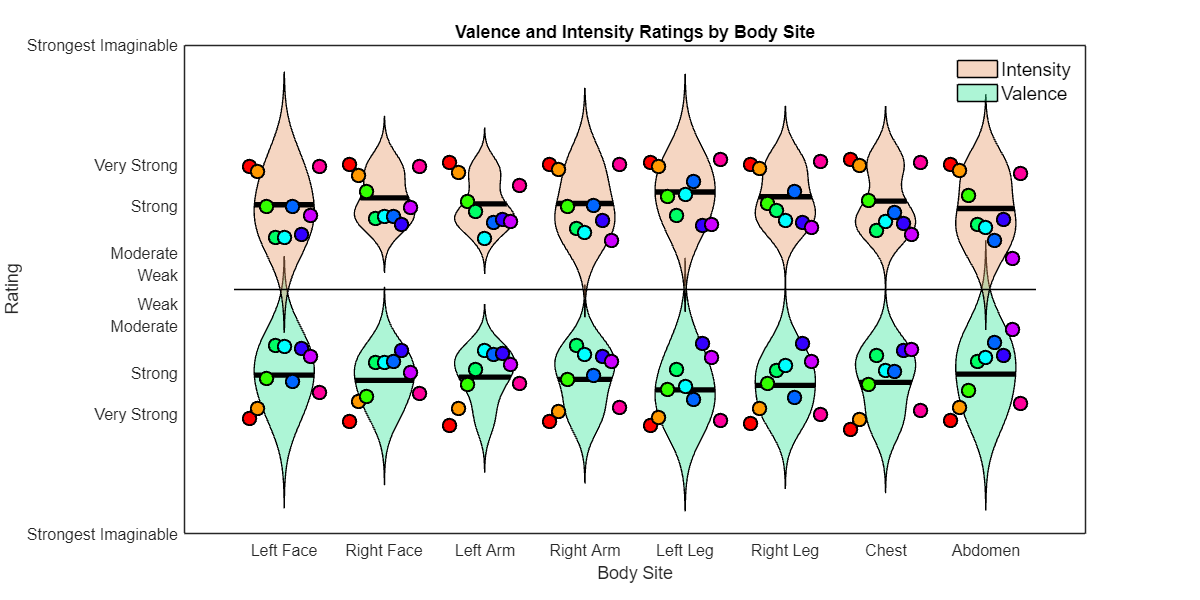

% 1) Prepare data matrices (subjects x bodysites)
intensity_data = intensity_means;  % [numSubjects x numBodysites]
valence_data   = valence_means;    % [numSubjects x numBodysites]

[numSubjects, numBodysites] = size(valence_data);

% 2) Create figure and axes
figure('Color','w', 'Position', [100 100 1200 600]);
ax = axes;
hold(ax, 'on');
set(ax, 'Layer', 'top');

positions = 1:numBodysites;

% 3) Violin plots with robust coloring
% Capture patches before/after each call to identify which belong to which
p0 = findobj(ax, 'Type', 'Patch');
v_val = violinplot(valence_data, positions, 'nopoints', 'mc', 'k');      % valence
p1 = findobj(ax, 'Type', 'Patch');
val_patches = setdiff(p1, p0);   % patches created by first call

v_int = violinplot(intensity_data, positions, 'nopoints', 'mc', 'k');    % intensity
p2 = findobj(ax, 'Type', 'Patch');
int_patches = setdiff(p2, p1);   % patches created by second call

% Set colors and alpha
val_color = [0.2 0.9 0.6];   % valence
int_color = [0.9 0.6 0.4];   % intensity

set(val_patches, 'FaceColor', val_color, 'FaceAlpha', 0.4);
set(int_patches, 'FaceColor', int_color, 'FaceAlpha', 0.4);

% 4) Add individual subject points
offset_range = 0.35;
offsets = linspace(-offset_range, offset_range, numSubjects);  % symmetric offsets

for b = 1:numBodysites
    x_center = positions(b);
    for s = 1:numSubjects
        x_pos = x_center + offsets(s);

        y_val = valence_data(s, b);
        y_int = intensity_data(s, b);

        % Valence point
        scatter(x_pos, y_val, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.5);

        % Intensity point
        scatter(x_pos, y_int, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.5);
    end
end

% Reference line at 0
hline(0, 'k-');

% 5) Final formatting
yticks(valence_ticks([1:5, 8:12]));
yticklabels(valence_ticklabels([1:5, 8:12]));

xticks(positions);
xticklabels(bodysite_labels);

xlabel('Body Site');
ylabel('Rating');
title('Valence and Intensity Ratings by Body Site');

% 6) Legend (stable, not dependent on internal patch order)
hInt = patch(NaN, NaN, int_color, 'FaceAlpha', 0.4);
hVal = patch(NaN, NaN, val_color, 'FaceAlpha', 0.4);
legend([hInt, hVal], {'Intensity', 'Valence'}, 'Location', 'northeast');

grid(ax, 'off');
set(ax, 'FontSize', 12, 'Box', 'on');
axis(ax, 'auto');
hold(ax, 'off');

## Figure S2B: Subject-Level Variability of In-fMRI Scanner Self-Report

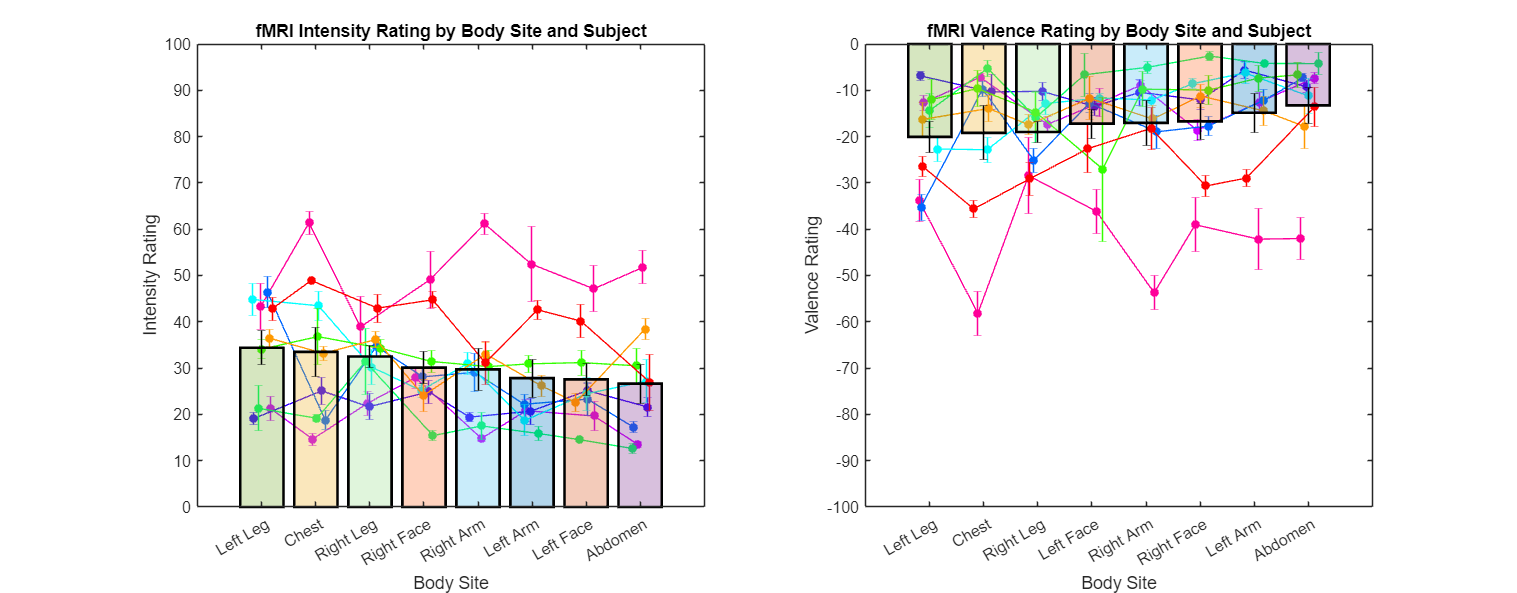

% ---------- Shared inputs ----------
intensity_metric = scan_data.intensity_rating;
valence_metric   = scan_data.valence_rating;

body_site  = scan_data.body_site;   % categorical or char
subjectid  = scan_data.subjectid;    % numeric subject IDs

% Main subjects
unique_subjects = unique(subjectid);

% Subject color scheme
colors = hsv(length(unique_subjects) + 1);
colors = colors([1:2, 4:end], :);  % drop one color

figure('Position', [0 0 2560 1000]);
%% ---------- Intensity (left subplot) ----------

[grand_mean_int, grand_se_int, subj_mean_int, subj_se_int, body_sites_ordered_int] = ...
    compute_stats_by_bodysite(intensity_metric, body_site, subjectid, ...
                              correct_order, unique_subjects);

% Save out expected variables
intensity_scan_mean     = grand_mean_int;
intensity_scan_se       = grand_se_int;
intensity_scan_sub_mean = subj_mean_int;
intensity_scan_sub_se   = subj_se_int;

% Sort by descending grand mean
[grand_mean_int_sorted, sort_idx_int] = sort(grand_mean_int, 'descend');
grand_se_int_sorted   = grand_se_int(sort_idx_int);
subj_mean_int_sorted  = subj_mean_int(sort_idx_int, :);
subj_se_int_sorted    = subj_se_int(sort_idx_int, :);

bs_colors_int = cmap(sort_idx_int, :);

subplot(1, 2, 1);
plot_body_site_bars_basic( ...
    grand_mean_int_sorted, grand_se_int_sorted, ...
    subj_mean_int_sorted, subj_se_int_sorted, ...
    body_sites_ordered_int(sort_idx_int), bs_colors_int, ...
    unique_subjects, colors);

xlabel('Body Site');
ylabel('Intensity Rating');
ylim([0 100]);
title('fMRI Intensity Rating by Body Site and Subject');

% Add legend (do it once, on the right subplot)
legend_labels = strcat('Subject-', cellstr(unique_subjects(:)));

% Preallocate graphic handles
nSubs = numel(unique_subjects);
legend_handles = gobjects(nSubs, 1);

% Create invisible dummy points just for the legend
hold on;
for s = 1:nSubs
    legend_handles(s) = plot(NaN, NaN, 'o', ...
        'MarkerFaceColor', colors(s, :), ...
        'MarkerEdgeColor', colors(s, :), ...
        'MarkerSize', 6, ...
        'LineStyle', 'none');
end

% Now make the legend from those dummy handles
legend(legend_handles, legend_labels, 'Location', 'BestOutside');
legend off;

%% ---------- Valence (right subplot) ----------

[grand_mean_val, grand_se_val, subj_mean_val, subj_se_val, body_sites_ordered] = ...
    compute_stats_by_bodysite(valence_metric, body_site, subjectid, ...
                              correct_order, unique_subjects);

% Save out expected variables
valence_scan_mean     = grand_mean_val;
valence_scan_se       = grand_se_val;
valence_scan_sub_mean = subj_mean_val;
valence_scan_sub_se   = subj_se_val;

% Sort by ascending grand mean
[grand_mean_val_sorted, sort_idx_val] = sort(grand_mean_val, 'ascend');
grand_se_val_sorted   = grand_se_val(sort_idx_val);
subj_mean_val_sorted  = subj_mean_val(sort_idx_val, :);
subj_se_val_sorted    = subj_se_val(sort_idx_val, :);

% Body-site colors for this ordering
bs_colors_val = cmap(sort_idx_val, :);

subplot(1, 2, 2);
plot_body_site_bars_basic( ...
    grand_mean_val_sorted, grand_se_val_sorted, ...
    subj_mean_val_sorted, subj_se_val_sorted, ...
    body_sites_ordered(sort_idx_val), bs_colors_val, ...
    unique_subjects, colors);

xlabel('Body Site');
ylabel('Valence Rating');
ylim([-100 0]);
title('fMRI Valence Rating by Body Site and Subject');

legend off;

## Figure S2B2: In-fMRI Scanner Self-Report

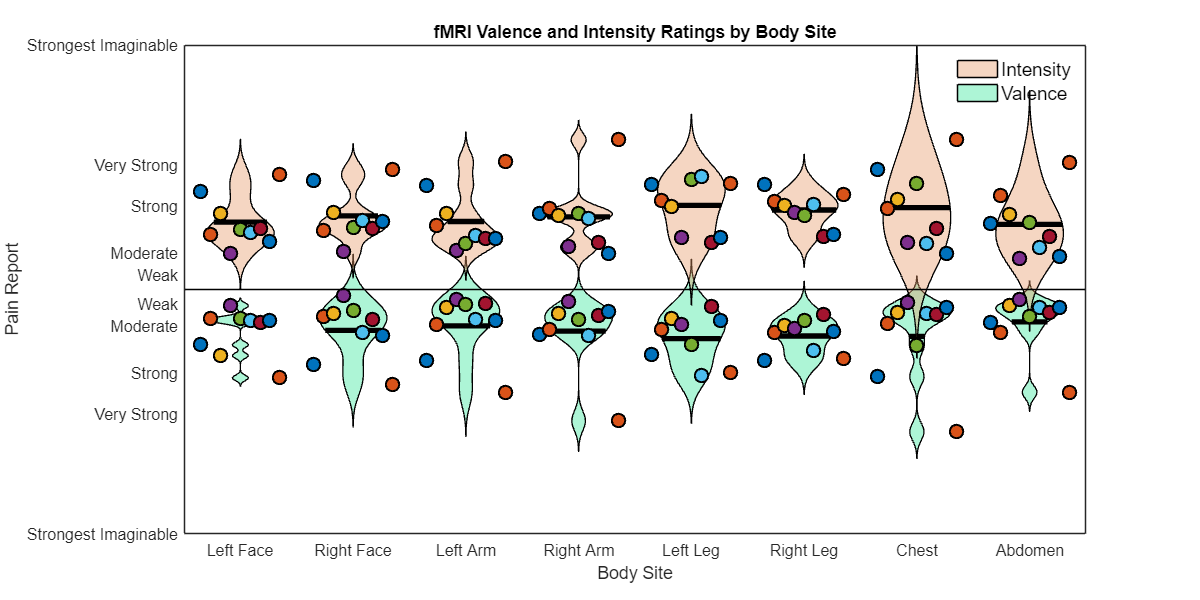

% 1) Prepare data matrices (subjects x bodysites)
valence_data   = valence_scan_sub_mean';    % [numSubjects x numBodysites]
intensity_data = intensity_scan_sub_mean';  % [numSubjects x numBodysites]

[numSubjects, numBodysites] = size(valence_data);

% 2) Create figure and axes
figure('Color', 'w', 'Position', [100 100 1200 600]);
ax = axes;
hold(ax, 'on');
set(ax, 'Layer', 'top');

positions = 1:numBodysites;

% 3) Violin plots with robust coloring
% Capture patches before/after each call
p0 = findobj(ax, 'Type', 'Patch');
v_val = violinplot(valence_data, positions, 'nopoints', 'mc', 'k');       % valence
p1 = findobj(ax, 'Type', 'Patch');
val_patches = setdiff(p1, p0);   % patches from first call

v_int = violinplot(intensity_data, positions, 'nopoints', 'mc', 'k');     % intensity
p2 = findobj(ax, 'Type', 'Patch');
int_patches = setdiff(p2, p1);   % patches from second call

% Set colors and alpha
val_color = [0.2 0.9 0.6];   % valence
int_color = [0.9 0.6 0.4];   % intensity

set(val_patches, 'FaceColor', val_color, 'FaceAlpha', 0.4);
set(int_patches, 'FaceColor', int_color, 'FaceAlpha', 0.4);

% 4) Add individual subject points
colors       = lines(numSubjects);
offset_range = 0.35;
offsets      = linspace(-offset_range, offset_range, numSubjects);  % symmetric offsets

for b = 1:numBodysites
    x_center = positions(b);
    for s = 1:numSubjects
        x_pos = x_center + offsets(s);

        y_val = valence_data(s, b);
        y_int = intensity_data(s, b);

        % Valence point
        scatter(x_pos, y_val, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.5);

        % Intensity point
        scatter(x_pos, y_int, 100, ...
            'MarkerFaceColor', colors(s, :), ...
            'MarkerEdgeColor', 'k', ...
            'LineWidth', 1.5);
    end
end

% Reference line at 0
hline(0, 'k-');

% 5) Final formatting
ylim([-100 100]);
yticks(valence_ticks([1:5, 8:12]));
yticklabels(valence_ticklabels([1:5, 8:12]));

xticks(positions);
xticklabels(bodysite_labels);

xlabel('Body Site');
ylabel('Pain Report');
title('fMRI Valence and Intensity Ratings by Body Site');

% 6) Legend (stable, not dependent on h(1), h(9), etc.)
hInt = patch(NaN, NaN, int_color, 'FaceAlpha', 0.4);
hVal = patch(NaN, NaN, val_color, 'FaceAlpha', 0.4);
legend([hInt, hVal], {'Intensity', 'Valence'}, 'Location', 'northeast');

grid(ax, 'off');
set(ax, 'FontSize', 12, 'Box', 'on');
hold(ax, 'off');

## Table S1: Calibration Temperatures and Pain Rating Metrics

fmt = @(x) compose('%.2f', x);

T = table( ...
    fmt(detection_thr_mean), fmt(detection_thr_se), ...
    fmt(pain_tol_mean), fmt(pain_tol_se), ...
    fmt(mean(valence_means)'), fmt(mean(valence_se)'), ...
    fmt(mean(intensity_means)'), fmt(mean(intensity_se)'), ...
    fmt(valence_scan_mean), fmt(valence_scan_se), ...
    fmt(intensity_scan_mean), fmt(intensity_scan_se), ...
    'VariableNames', {'Detection Threshold M','Detection Threshold SE','Pain Tolerance M','Pain Tolerance SE', ...
    'Calibration Valence Rating M','Calibration Valence Rating SE','Calibration Intensity Rating M','Calibration Intensity Rating SE', ...
    'Scanner Valence Rating M','Scanner Valence Rating SE','Scanner Intensity Rating M','Scanner Intensity Rating SE'}, ...
    'RowNames', bodysite_labels);
disp(T)

                  Detection Threshold M    Detection Threshold SE    Pain Tolerance M    Pain Tolerance SE    Calibration Valence Rating M    Calibration Valence Rating SE    Calibration Intensity Rating M    Calibration Intensity Rating SE    Scanner Valence Rating M    Scanner Valence Rating SE    Scanner Intensity Rating M    Scanner Intensity Rating SE
                  _____________________    ______________________    ________________    _________________    ____________________________    _____________________________    ______________________________    _______________________________    ________________________    ____

## Mixed Effects Modelling

% Calibration Behavior
final_mdls_1storder{1}=fitlme(calibration_data, 'stim_temp ~ 1 + trial + repetition + body_site + (trial + repetition + body_site| subjectid)', 'FitMethod', 'REML');
final_mdls_1storder{2}=fitlme(calibration_data, 'hot_temp ~ 1 + trial + repetition + body_site + (trial + repetition + body_site | subjectid)', 'FitMethod', 'REML');

% Calibration Ratings
final_mdls_1storder{3}=fitlme(calibration_data, 'intensity_rating ~ 1 + trial + repetition + body_site + (trial + repetition + body_site| subjectid)', 'FitMethod', 'REML');
final_mdls_1storder{4}=fitlme(calibration_data, 'valence_rating ~ 1 + trial + repetition + body_site + (trial + repetition + body_site| subjectid)', 'FitMethod', 'REML');

% Scanner Ratings
final_mdls_1storder{5}=fitlme(scan_data, 'intensity_rating ~ 1 + session + run + body_site + (session + run + body_site | subjectid)', 'FitMethod', 'REML');
final_mdls_1storder{6}=fitlme(scan_data, 'valence_rating ~ 1 + session + run + body_site + (session + run + body_site | subjectid)', 'FitMethod', 'REML');

## Omnibus Test of Body Site Differences for Each Outcome

outcomes = {'detection_threshold', 'pain_tolerance', 'calibration_intensity', 'calibration_valence', 'scan_intensity', 'scan_valence'};

           ModelIndex            DF1     DF2      Fstat       pValue      SS_body    SS_resid    Eta2_partial
    _________________________    ___    ______    ______    __________    _______    ________    ____________

    {'detection_threshold'  }     7     14.934    5.2906     0.0033674    230.15      92.806       0.71263   
    {'pain_tolerance'       }     7     12.619    13.666    5.4381e-05    74.317       9.803       0.88346   
    {'calibration_intensity'}     7      13.23    1.4488       0.26618     381.9      498.19       0.43393   
    {'calibration_valence'  }     7     15.091    1.4472        0.2581    530.32      789.99       0.40166   
    {'scan_intensity'       }     7     10.123    2.1576       0.12

levels = {'Abdomen', 'Chest', 'Left Arm', 'Left Face', 'Left Leg', 'Right Arm', 'Right Face', 'Right Leg'};

eta_results = table();

for i = 1:numel(final_mdls_1storder)

        Site1             Site2           Fstat      DF1    DF2       pval        pval_fdr     pval_bonf 
    ______________    ______________    _________    ___    ___    __________    __________    __________
    {'Left Face' }    {'Right Face'}       0.1237     1     278       0.72533       0.92314             1
    {'Left Face' }    {'Left Arm'  }        10.56     1     278     0.0012975      0.007266       0.03633
    {'Left Face' }    {'Right Arm' }       8.8005     1     278     0.0032732      0.013093       0.09165
    {'Left Face' }    {'Left Leg'  }     0.012279     1     278       0.91185       0.95598             1
    {'Left Face' }    {'Right Leg' }     0.044299     1     278       0.83345          0.94 

    lme = final_mdls_1storder{i};
    a = anova(lme, 'DFMethod', 'Satterthwaite');
    mse = lme.MSE;


        Site1             Site2           Fstat      DF1    DF2       pval        pval_fdr     pval_bonf 
    ______________    ______________    _________    ___    ___    __________    __________    __________
    {'Left Face' }    {'Right Face'}       1.3889     1     277       0.23961       0.37272             1
    {'Left Face' }    {'Left Arm'  }       51.513     1     277    6.5397e-12    9.1555e-11    1.8311e-10
    {'Left Face' }    {'Right Arm' }       12.428     1     277    0.00049461     0.0017311      0.013849
    {'Left Face' }    {'Left Leg'  }       9.5125     1     277      0.002247     0.0057197      0.062917
    {'Left Face' }    {'Right Leg' }       26.827     1     277    4.2875e-07    4.0017e-06 

    % Identify body_site row in ANOVA table
    idx = strcmp(a.Term, 'body_site');

    if any(idx)
        F     = a.FStat(idx);
        df1   = a.DF1(idx);
        df2   = a.DF2(idx);
        pval  = a.pValue(idx);

        % Compute sums of squares
        SS_body = F * mse * df1;
        SS_resid = mse * df2;

        % Partial eta squared
        eta2_partial = SS_body / (SS_body + SS_resid);

        % Store results
        eta_results = [eta_results; table(outcomes(i), df1, df2, F, pval, SS_body, SS_resid, eta2_partial, ...
            'VariableNames', {'ModelIndex', 'DF1', 'DF2', 'Fstat', 'pValue', ...
                              'SS_body', 'SS_resid', 'Eta2_partial'})];
    else
        warning('body_site not found in model %d', i);
    end

end

disp(eta_results)

Here we see that the effects of body site in calibration behavior but not for self-report ratings either in the calibration or scanning sessions.

## Post-Hoc Detection Threshold

posthoc_body_site = pairwise_body_site_contrasts(final_mdls_1storder{1}, 'body_site');
disp(posthoc_body_site)

## Post-Hoc Pain Tolerance Threshold

posthoc_body_site = pairwise_body_site_contrasts(final_mdls_1storder{2}, 'body_site');
disp(posthoc_body_site)

## Functions

function results = pairwise_body_site_contrasts(lme, varname)
% lme      : fitted LinearMixedModel (from fitlme)
% varname  : name of the categorical variable to compare (e.g., 'body_site')
%
% returns  : table of pairwise comparisons with F and p-values

    % Ensure varname is categorical
    if ~iscategorical(lme.Variables.(varname))
        error('%s must be categorical', varname);
    end

    % Get levels of the categorical variable
    levels = categories(lme.Variables.(varname));
    n_levels = numel(levels);
    pairs = nchoosek(1:n_levels, 2);

    % Get names and positions of fixed effects
    [~,names] = fixedEffects(lme);
    names = names.Name;

    % Find all dummy variable indices for the categorical variable
    var_prefix = [varname, '_'];
    idx_cat = find(contains(names, var_prefix));

    if isempty(idx_cat)
        error('No fixed effect terms found for %s', varname);
    end

    % Find dummy variable indices for body_site (exclude intercept and covariates)
    body_site_prefix = 'body_site_';
    idx_cat = find(startsWith(names, body_site_prefix));
    n_fixed = numel(names);  % Total number of fixed effects
    
    % Initialize results table
    results = table();
    
    for i = 1:size(pairs,1)
        i1 = pairs(i,1);
        i2 = pairs(i,2);
    
        c = zeros(1, n_fixed);  % Ensure correct size
    
        % MATLAB uses reference coding: body_site level 1 (e.g., Left Face) is baseline
        % So if i1 == 1, its coefficient is implicitly 0
        if i1 > 1
            c(idx_cat(i1 - 1)) = 1;
        end
        if i2 > 1
            c(idx_cat(i2 - 1)) = c(idx_cat(i2 - 1)) - 1;
        end
    
        % Run Wald test on contrast
        [p, F, df1, df2] = coefTest(lme, c);
    
        % Store result
        results = [results; table(levels(i1), levels(i2), F, df1, df2, p, ...
            'VariableNames', {'Site1', 'Site2', 'Fstat', 'DF1', 'DF2', 'pval'})];
    end

    % Add FDR and Bonferroni corrections
    results.pval_fdr = mafdr(results.pval, 'BHFDR', true);
    results.pval_bonf = min(results.pval * height(results), 1);

end



function [grand_mean, grand_se, subj_mean, subj_se] = ...
    compute_subject_stats(y, body_site, subjectid, unique_body_sites, unique_subjects)
% Compute subject-level means/SE and grand mean/SE per body site

nSites  = numel(unique_body_sites);
nSubs   = numel(unique_subjects);

subj_mean = nan(nSites, nSubs);
subj_se   = nan(nSites, nSubs);
grand_mean = nan(nSites, 1);
grand_se   = nan(nSites, 1);

for i = 1:nSites
    idx_site = strcmp(body_site, unique_body_sites{i});

    for j = 1:nSubs
        idx_subj = idx_site & strcmp(subjectid, unique_subjects{j});
        this_y   = y(idx_subj);

        subj_mean(i, j) = nanmean(this_y);
        subj_se(i, j)   = nanstd(this_y) ./ sqrt(sum(~isnan(this_y)));
    end

    % Grand stats across subjects (ignore NaNs)
    grand_mean(i) = nanmean(subj_mean(i, :));

    % SE of the subject means (not of SEs)
    valid_means   = subj_mean(i, :);
    grand_se(i)   = nanstd(valid_means) ./ sqrt(sum(~isnan(valid_means)));
end
end

function plot_body_site_bars(grand_mean, grand_se, ...
    subj_mean, subj_se, body_sites, bs_colors, unique_subjects, colors)
% Plot bar + jittered subject means with error bars

nSites = numel(body_sites);

% Bar plot of grand means
bar_handle = bar(grand_mean, 'FaceColor', [0.9 0 0], ...
    'FaceAlpha', 0.3, 'LineWidth', 2);
hold on;

% Apply per-bar colors
bar_handle.FaceColor = 'flat';
bar_handle.CData     = bs_colors;

% Subject means as jittered dots + error bars, behind bars
for j = 1:length(unique_subjects)
    x_jitter = (rand(nSites, 1) - 0.5) * 0.4;

    % Line connecting subject's points
    line_handle = plot((1:nSites)' + x_jitter, subj_mean(:, j), ...
        'Color', colors(j, :), 'LineWidth', 1);
    uistack(line_handle, 'bottom');

    % Error bars
    eh = errorbar((1:nSites)' + x_jitter, subj_mean(:, j), subj_se(:, j), 'o', ...
        'MarkerSize', 6, ...
        'MarkerEdgeColor', colors(j, :), ...
        'MarkerFaceColor', colors(j, :), ...
        'Color', colors(j, :), ...
        'LineStyle', 'none');
    uistack(eh, 'bottom');
end

% Error bars on grand means
errorbar(1:nSites, grand_mean, grand_se, 'k', 'LineStyle', 'none');

% X labels
set(gca, 'XTick', 1:nSites, 'XTickLabel', body_sites);

hold off;
end

function [grand_mean, grand_se, subj_mean, subj_se, body_sites_ordered] = ...
    compute_stats_by_bodysite(y, body_site, subjectid, correct_order, unique_subjects)
% y              : vector of ratings (valence/intensity)
% body_site      : categorical/char body-site labels
% subjectid      : numeric subject IDs
% correct_order  : cellstr with desired body-site order
% unique_subjects: vector of subject IDs to include (e.g., first 9)

    body_site = cellstr(body_site);
    all_sites = unique(body_site);

    % Reorder body sites according to correct_order
    [~, loc] = ismember(correct_order, all_sites);
    keep     = loc > 0;
    body_sites_ordered = correct_order(keep);
    nSites   = numel(body_sites_ordered);
    nSubs    = numel(unique_subjects);

    subj_mean = nan(nSites, nSubs);
    subj_se   = nan(nSites, nSubs);
    grand_mean = nan(nSites, 1);
    grand_se   = nan(nSites, 1);

    for i = 1:nSites
        idx_site = strcmp(body_site, body_sites_ordered{i});

        for j = 1:nSubs
            idx_subj = idx_site & subjectid == unique_subjects(j);
            this_y   = y(idx_subj);

            subj_mean(i, j) = nanmean(this_y);
            subj_se(i, j)   = nanstd(this_y) ./ max(1, sqrt(sum(~isnan(this_y))));
        end

        % Grand stats across subjects (ignore NaNs)
        grand_mean(i) = nanmean(subj_mean(i, :));
        valid_means   = subj_mean(i, :);
        grand_se(i)   = nanstd(valid_means) ./ max(1, sqrt(sum(~isnan(valid_means))));
    end
end


function plot_body_site_bars_basic(grand_mean, grand_se, ...
    subj_mean, subj_se, body_sites, bs_colors, unique_subjects, colors)
% Reusable plotting helper: bar + jittered subject means + SEs

    nSites = numel(body_sites);

    % Bar plot of grand means
    bar_handle = bar(grand_mean, 'FaceColor', [0.9 0 0], ...
        'FaceAlpha', 0.3, 'LineWidth', 2);
    hold on;

    % Apply per-bar colors
    bar_handle.FaceColor = 'flat';
    bar_handle.CData     = bs_colors;

    % Subject means as jittered dots + error bars, behind bars
    for j = 1:length(unique_subjects)
        x_jitter = (rand(nSites, 1) - 0.5) * 0.4;

        % Line connecting subject's points
        line_handle = plot((1:nSites)' + x_jitter, subj_mean(:, j), ...
            'Color', colors(j, :), 'LineWidth', 1);
        uistack(line_handle, 'bottom');

        % Error bars
        eh = errorbar((1:nSites)' + x_jitter, subj_mean(:, j), subj_se(:, j), 'o', ...
            'MarkerSize', 6, ...
            'MarkerEdgeColor', colors(j, :), ...
            'MarkerFaceColor', colors(j, :), ...
            'Color', colors(j, :), ...
            'LineStyle', 'none');
        uistack(eh, 'bottom');
    end

    % Error bars on grand means
    errorbar(1:nSites, grand_mean, grand_se, 'k', 'LineStyle', 'none');

    % X labels
    set(gca, 'XTick', 1:nSites, 'XTickLabel', body_sites);

    set(gca, 'Box', 'on', 'FontSize', 12);
    hold off;
end
